# **InverseGaussSL**

Inverse lemniscate sine function

## Definition


$${s\textrm{l}}^{-1} x=\int_0^x \frac{\textrm{dt}}{\sqrt{1-t^4 }}$$


Domain: $-1\le x\le 1$. For the specified domain, the  codomain is the set of real numbers.

Special values:

   
$${\mathrm{sl}}^{-1} \left(0\right)=0$$


Identities:

## Syntax

Y = InverseGaussSL(X)

y = igsl(x)

## Description

**Y = InverseGaussSL(X)** returns the value of the inverse lemniscate sine function ${\mathrm{sl}}^{-1} x$ for each element of the array  X .  X must be real array or scalar. **InverseGaussSL** is the wrapper function which calls the functions **igsl** element-wise via the function **ufun1**.

**y = igsl(x)** returns the value of the inverse lemniscate cosine function ${\mathrm{sl}}^{-1} x$ for  x. It is assumed that  x is real scalars without check. y is NaN if x is invalid or convergence failed. **igsl** calculate ${\mathrm{sl}}^{-1} x$ by clalling Carlson's fuunction **rf**.

## Precision

## **Numerical Examples**

**Scalar input**

format long
x = 1/2; 
[igsl(x), InverseGaussSL(x)]

ans =    0.503209443177331   0.503209443177331


Accuracy. 

fprintf('%.16g\n',igsl(1/2)) 

0.503209443177331


% Maple 0.503209443177330 887

Special values

igsl(0)

ans = 0

Identities

x = pi/4;
disp(igsl(gsl(x))-x)

    -3.330669073875470e-16



disp(gsl(igsl(x))-x)

     0



**Vector input**

x=[1e-6 0.2 -0.3 -1e-20];
disp(GaussSL(InverseGaussSL(x))-x)

   1.0e-16 *

                   0                   0   0.555111512312578                   0



**Matrix input**

x=[-1/2 1/3 1/4; 1/2 -1/3 -1/4];
disp(GaussSL(InverseGaussSL(x))-x)

   1.0e-15 *

  -0.111022302462516                   0  -0.111022302462516
   0.111022302462516                   0   0.111022302462516



## **Plot**

**Example 1**

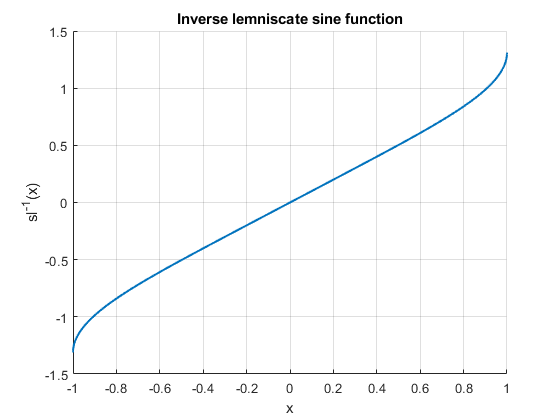

figure
hold on
fplot(@(x) InverseGaussSL(x),[-1 1],'LineWidth',1.5,'MeshDensity',200)
title('Inverse lemniscate sine function')
xlabel('x')
ylabel('sl^{-1}(x)')
grid on

**Example 2**

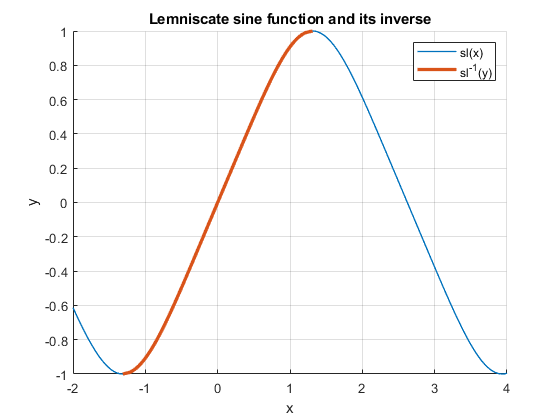

figure
hold on
x=-2:0.01:4;
plot(x,GaussSL(x),'LineWidth',1)
plot(InverseGaussSL(x),x,'LineWidth',2.5)
title('Lemniscate sine function and its inverse')
legend('sl(x)','sl^{-1}(y)')
xlabel('x')
ylabel('y')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Lemniscatic elliptic function, Wikipedia](https://en.wikipedia.org/wiki/Lemniscatic_elliptic_function)

[Lemniscate functions, Encyclopedia of Mathematics](https://www.encyclopediaofmath.org/index.php/Lemniscate_functions)

## **References**

[1] E.T. Whittaker, G.N. Watson, A course of modern analysis, 4. ed., Cambridge Univ. Pr., Cambridge, 1996.

[2]  [W.Ehrhardt, The AMath and DMath Special functions, 2016](http://www.wolfgang-ehrhardt.de/specialfunctions.pdf)

## See Also